### EE125 Project 6 - FIR Filter Design

December 7, 2024

## Part 1: Filter Design by Frequency Sampling

Design a filter h(n) with this spec:

Fs = 5000 Hz

L   = 41 (filter length)

Lowpass Response: 1 for F < 750 Hz, 0 otherwise.

Step 1: Create a vector of frequencies, F, that is of length, L. The first frequency sample in vector F should be 0 Hz, L samples should cover interval [0, Fs).

% Parameters
Fs = 5000; % in Hz
L  = 41;
Fc = 750; % Cut off freq. in Hz

% Evenly spaced frequencies for F
F = (0:L-1) * (Fs / L);

disp(F);

   1.0e+03 *

         0    0.1220    0.2439    0.3659    0.4878    0.6098    0.7317    0.8537    0.9756    1.0976    1.2195    1.3415    1.4634    1.5854    1.7073    1.8293    1.9512    2.0732    2.1951    2.3171    2.4390    2.5610    2.6829    2.8049    2.9268    3.0488    3.1707    3.2927    3.4146    3.5366    3.6585    3.7805    3.9024    4.0244    4.1463    4.2683    4.3902    4.5122    4.6341    4.7561    4.8780



length(F)

ans = 41

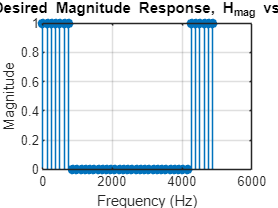


% Magnitude response
Hmag = F < Fc; % Set Hmag to 1 where F < 750 Hz, otherwise 0
% Conjugate-symmetric frequency response
% Filter is low pass, need to include negative!
% 6 points on right side, would be shifted to neg.
Hmag = Hmag + (F > (Fs - Fc));

% Plot the magnitude response
figure;
stem(F, Hmag, 'filled');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Desired Magnitude Response, H_{mag} vs. F');
grid on;

Our desired magnitude response looks exactly as expected. Yippee! (End of Page 2)

Create Hphase so filter will be causal. Has linear phase relationship. Ensure phase at 0 is F=0Hz, and conjugate symmetry

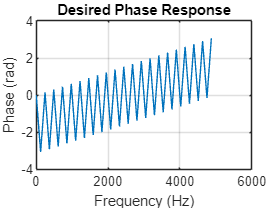

% Shift in time to let Hphase be causal
M = (L-1)/2;

% Discrete frequency step
dw = 2*pi / L;

% Phase vector using continuous-time frequency (used method 2)
% F is from above, F = (0:L-1) * (Fs / L);
Hphase = exp(-1j * M * 2 * pi * F / Fs);

% Plot the phase response
figure;
plot(F, angle(Hphase));
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
title('Desired Phase Response');
grid on;

Complex-valued Frequency Response, H=Hmag .* Hphase; as well as h=ifft(H). Imaginary values of h(n) should be very small. They are!

H = Hmag .* Hphase

H =    1.0000 + 0.0000i  -0.9971 - 0.0765i   0.9883 + 0.1526i  -0.9737 - 0.2279i   0.9534 + 0.3017i  -0.9275 - 0.3738i   0.8962 + 0.4437i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.8962 - 0.4437i  -0.9275 + 0.3738i   0.9534 - 0.3017i  -0.9737 + 0.2279i   0.9883 - 0.1526i  -0.9971 + 0.0765i


h=ifft(H)

h =    0.0214 + 0.0000i   0.0019 + 0.0000i  -0.0198 - 0.0000i  -0.0238 - 0.0000i  -0.0059 - 0.0000i   0.0185 - 0.0000i   0.0273 - 0.0000i   0.0109 - 0.0000i  -0.0176 - 0.0000i  -0.0326 - 0.0000i  -0.0180 + 0.0000i   0.0170 + 0.0000i   0.0421 + 0.0000i   0.0304 + 0.0000i  -0.0166 - 0.0000i  -0.0629 - 0.0000i  -0.0603 - 0.0000i   0.0163 - 0.0000i   0.1458 + 0.0000i   0.2674 + 0.0000i   0.3171 + 0.0000i   0.2674 + 0.0000i   0.1458 + 0.0000i   0.0163 - 0.0000i  -0.0603 - 0.0000i  -0.0629 - 0.0000i  -0.0166 - 0.0000i   0.0304 + 0.0000i   0.0421 + 0.0000i   0.0170 + 0.0000i  -0.0180 + 0.0000i  -0.0326 + 0.0000i  -0.0176 - 0.0000i   0.0109 - 0.0000i   0.0273 - 0.0000i   0.0185 - 0.0000i  -0.0059 - 0.0000i  -0.0238 - 0.0000i  -0.0198 - 0.0000i   0.0019 + 0.0000i   0.0214 + 0.0000i


hreal = real(h);

Plot h(n), which should look like a sinc function. It does!

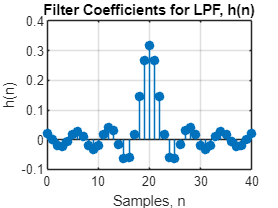

n = 0:1:L-1;
figure;
stem(n, hreal, "filled");
xlabel('Samples, n');
ylabel('h(n)');
title('Filter Coefficients for LPF, h(n)');
grid on;

Plot the magnitude and phase response of the filter. Importantly, we need to zero-pad to a greater length than 41, eg. 512 so we don't just get back the samples at our original ideal state. Or, use built in function freqz(h, 1, 512, 5000); See effects in Spectrum Estimation Slide 29.

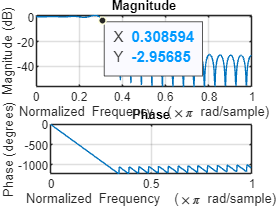

% FFT to get samples in time to frequency!
Hplot = fft(h, 512);
Fplot = (0:512-1) * (Fs / 512);

% Magnitude Response
Hplot_mag = abs(Hplot);

% Phase Response
Hplot_phase = angle(Hplot);

% % Plot magnitude response of filter.
% figure;
% subplot(2, 1, 1);
% plot(Fplot, mag2db(Hplot_mag));
% xlabel('Frequency (Hz)');
% ylabel('Magnitude (dB)');
% title('Magnitude Response of the Filter');
% grid on;
% 
% % Plot phase response.
% subplot(2, 1, 2);
% plot(Fplot, unwrap(Hplot_phase)); % Unwrap phase for continuity
% xlabel('Frequency (Hz)');
% ylabel('Phase (radians)');
% title('Phase Response of the Filter');
% grid on;
% hold off;

% Better to just use built in functions...
figure;
freqz(h);
ax = gca;
freqzchart = ax.Children(1);
% Can't quite get to -3db, but this is the closest
% [0.308593750000000,-2.956845442494000]
datatip(freqzchart,0.308593750000000,-2.956845442494000);

#### Effect of Transistion Band

Characterize filter performance. Create zoomed plot showing response in the passband, then measure and label the maximum error. What frequency is this error the largest (deviation from ideal desired of 1)?

error_mag (max passband error) = 1.1155

% Plot Filter Mag in dB.
figure;
plot(Fplot, mag2db(Hplot_mag));

xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Zoomed Plot with Max Passband Error');
grid on;

% Find max passband error and annotate
[H_max_passband_error, Hmpbe_error_index] = max(Hplot_mag)

H_max_passband_error = 1.1265

Hmpbe_error_index = 71

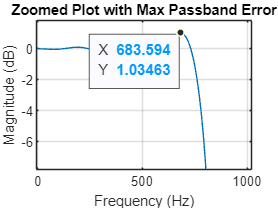


ax = gca;
chart = ax.Children(1);
% datatip(chart,Hmpbe_error_index,H_max_passband_error);
datatip(chart, 683.593750000000,0.949226504919851);

xlim([-537 5463])
ylim([-41 23])

xlim([-6 1022])
ylim([-7.8 1.8])

Find the max error in the stopband.

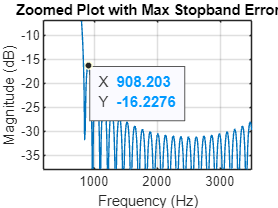

% Plot Filter Mag in dB
figure;
plot(Fplot, mag2db(Hplot_mag));

xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Zoomed Plot with Max Stopband Error');
grid on;

% Find max stopband error and annotate (clicked on).
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,908.2,-15.83);

xlim([204 3500])
ylim([-38.0 -7.0])

#### Design Filter with Slower Transistion

Design Hmag2 so it has 1-sample transistion band, setting desired response to 0.5 at one point between passband and stopband. Ensure same number of '1 values in passband as first design.

% Find the index for the transistion band.
% index_lastone_Hmag = find(Hmag == 1, 1, 'last');
index_transition_pos = 8

index_transition_pos = 8

index_transition_neg = L - 6

index_transition_neg = 35

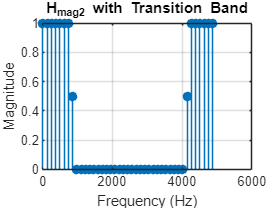


Hmag2 = double(Hmag);
Hmag2(1, index_transition_pos) = 0.5;
Hmag2(1, index_transition_neg) = 0.5;


% check Hmag2 - its proper
figure;
stem(F, Hmag2, 'filled');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('H_{mag2} with Transition Band');
grid on;

Calculate filter coefficients for h2(n) with new Hmag2 like before.

% No change to Hphase. Therefore, Hphase is same.
H2 = Hmag2 .* Hphase;
h2=ifft(H2);
h2real = real(h2);

#### Compare Designs

Graph h(n) and h2(n) in same axes.

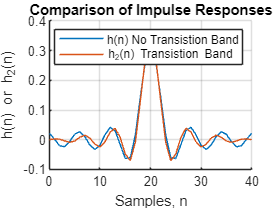

figure;
hold on;
plot(n, hreal);

plot(n, h2real);
xlabel('Samples, n');
ylabel('h(n) or h_{2}(n)');
title('Comparison of Impulse Responses');
grid on;
hold off;
legend('h(n) No Transistion Band', 'h_{2}(n) Transistion Band');

Find max passband and stopband errors of new filter.

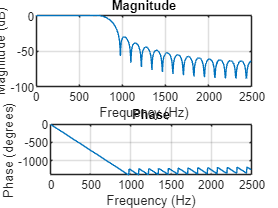

% Coefficient in denominator is 1 as signal is real, no poles.
H2plot = freqz(h2real, 1, 512, 5000);

% Show plot
freqz(h2real, 1, 512, 5000)


% Find max passband and stopband errors
H2plot_mag = abs(H2plot);

[H2_max_passband_error, H2mpbe_index] = max(H2plot_mag)

H2_max_passband_error = 1.0324

H2mpbe_index = 141

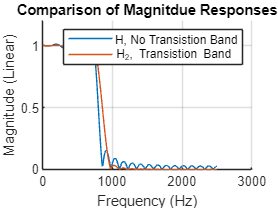


half_length = 512/2;
Fplot_halved = linspace(0, Fs/2, length(Hplot_mag(1:half_length)));
Fplot2 = linspace(0, Fs/2, 512);

figure;
hold on;
plot(Fplot_halved, Hplot_mag(1:half_length));


plot(Fplot2, H2plot_mag);
xlabel('Frequency (Hz)');
ylabel('Magnitude (Linear)');
title('Comparison of Magnitdue Responses');
grid on;
ax3 = gca;
chart3 = ax3.Children(1);
hold off;
legend('H, No Transistion Band', 'H_{2}, Transistion Band');

#### Optimize the Transistion Sample Value

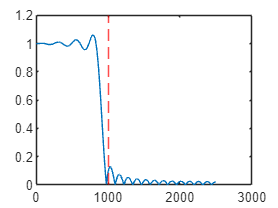

Hmag3 = double(Hmag2);
transition_value = 0.9;
Hmag3(1, index_transition_pos) = transition_value;
Hmag3(1, index_transition_neg) = transition_value;
H3 = Hmag3 .* Hphase;
h3=ifft(H3);
H3plot = freqz(real(h3), 1, 512, 5000);
plot(Fplot2, abs(H3plot));
xline(1000, '--r')

grid on

ans =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: any


ans =   Map with properties:

        Count: 5
      KeyType: char
    ValueType: any



xlim([877 1271])
ylim([0.000 0.133])

% Transition Band Value | Largest Error for >= 1000Hz
% 0.1                   | 0.0655571
% 0.2                   | 0.0415017
% 0.3                   | 0.0190492
% 0.4                   | 0.00961277
% 0.5                   | 0.032615
% 0.6                   | 0.0566924
% 0.7                   | 0.0809333
% 0.8                   | 0.105174
% 0.9                   | 0.129415